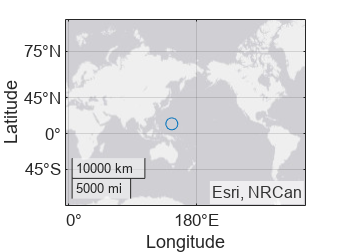

geoscatter(airports.LATITUDE,airports.LONGITUDE)

geolimits([-76 85],[-208 176])

flights=importFlightsData("flightsFeb.csv")

flights = 429191×20 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    _____________________    ____________

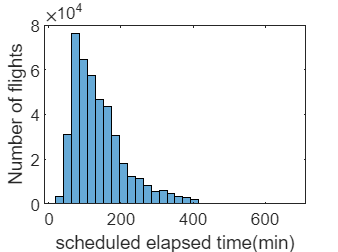

histogram(flights.SCHEDULED_ELAPSED_TIME,30)
xlabel("scheduled elapsed time(min)")
ylabel("Number of flights")

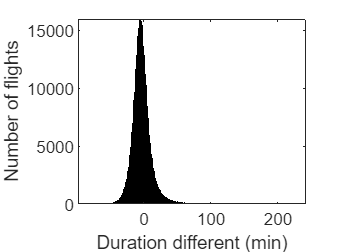

flights.DURATION_DIFF=flights.ACTUAL_ELAPSED_TIME-flights.SCHEDULED_ELAPSED_TIME;
histogram(flights.DURATION_DIFF);
xlabel("Duration different (min)")
ylabel("Number of flights")

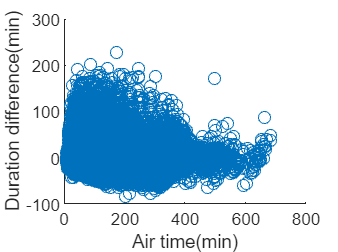

scatter(flights.AIR_TIME,flights.DURATION_DIFF)
xlabel("Air time(min)")
ylabel("Duration difference(min)")

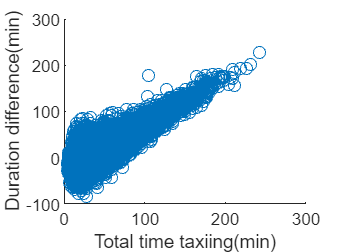

flights.TAXI_TOTAL=flights.TAXI_OUT+flights.TAXI_IN;
scatter(flights.TAXI_TOTAL,flights.DURATION_DIFF);
xlabel("Total time taxiing(min)")
ylabel("Duration difference(min)")

corr(flights.TAXI_TOTAL,flights.DURATION_DIFF,"rows","complete")

ans = 0.6976

flights(135:140,:)

ans = 6×22 table
              AIRLINE              TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED    DURATION_DIFF    TAXI_TOTAL
    ___________________________    ___________    _____________    ______    ___________    _______________________

flightsCan=flights(flights.CANCELLED==1,:);
numberCancelled=height(flightsCan)

numberCancelled = 20517

percentCancelled=numberCancelled/height(flights)*100

percentCancelled = 4.7804

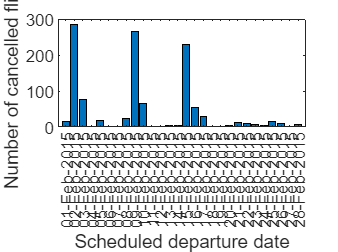

cancelledAirport=flightsCan(flightsCan.ORIGIN=="BOS",:);
cancelledAirportSummary=groupsummary(cancelledAirport,'SCHEDULED_DEPARTURE_TIME','day');
bar(cancelledAirportSummary.day_SCHEDULED_DEPARTURE_TIME,cancelledAirportSummary.GroupCount)
xlabel("Scheduled departure date")
ylabel("Number of cancelled flights.")